% 
BridgeCell = original_bridge;
ResultCell_InternalForce = data_internalforce;
ResultCell_Displacement = data_displacement;
for i=1:length(BridgeCell)
    bridgeobj = BridgeCell{i};
    result_InternalForce = ResultCell_InternalForce{i};
    result_Displacement = ResultCell_Displacement{i};
    nodes = allocateDisplacementToNodes(bridgeobj,result_Displacement);
    [elems_link,elems_beam] = allocateInternalForceToElement(bridgeobj,result_InternalForce);
end

girders = bridgeobj.findStructureByClass('Girder');
elems_girders = [];
for i=1:length(girders)
    girder = girders{i};
    elems_girders = [elems_girders,girder.Element];
end
sorted_elems_girders = elems_girders.sortByCenterPoint('X');

inodes = [];
jnodes = [];
for i=1:length(sorted_elems_girders)
    elem = sorted_elems_girders(i);
    inodes = [inodes,elem.INode];
    jnodes = [jnodes,elem.JNode];
end
X_inodes = [inodes.X];
Y_inodes = [inodes.Y];
Z_inodes = [inodes.Z];
X_jnodes = [jnodes.X];
Y_jnodes = [jnodes.Y];
Z_jnodes = [jnodes.Z];

Force_LocalCoord = [sorted_elems_girders.Force_LocalCoord];
Myi = Force_LocalCoord(5,:);
Myj = Force_LocalCoord(11,:);

multiplier = 50;
Z_Myi = Z_inodes + multiplier*Myi/max(abs(Myi));
Z_Myj = Z_jnodes + multiplier*Myj/max(abs(Myj));

X = [X_inodes;X_jnodes];
Y = [Y_inodes;Y_jnodes];
Z = [Z_Myi;Z_Myj];

[fig,ax] = bridgeobj.plot('ifPlotConstraint',true,'ifPlotCoupling',false,'ifPlotLoad',false);
multiplier = 10;
[X_nodes,Y_nodes,Z_Uz,Uz,fig,ax] = plotTowerBendingMoment(bridgeobj,multiplier,fig,ax)

X_nodes =    13.4500   17.4500   17.4500   21.4500   21.4500   25.4500   25.4500   29.4500   29.4500   33.4500   33.4500   34.5750   34.5750   35.7000   35.7000   36.8250   36.8250   37.9500   37.9500   39.0750   39.0750   40.2000   40.2000   41.3250   41.3250   42.4500   42.4500   43.5750   43.5750   44.7000   44.7000   45.8250   45.8250   46.9500   46.9500   48.0750   48.0750   49.2000   49.2000   50.3250   50.3250   51.4500   51.4500   52.5750   52.5750   53.7000   53.7000   54.8250   54.8250   55.9500


Y_nodes =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Z_Uz =    -4.2000   -4.0591   -4.0591   -3.9204   -3.9204   -3.7867   -3.7867   -3.6610   -3.6610   -3.5461   -3.5461   -3.5307   -3.5307   -3.5164   -3.5164   -3.5031   -3.5031   -3.4910   -3.4910   -3.4798   -3.4798   -3.4689   -3.4689   -3.4597   -3.4597   -3.4523   -3.4523   -3.4466   -3.4466   -3.4426   -3.4426   -3.4405   -3.4405   -3.4400   -3.4400   -3.4410   -3.4410   -3.4436   -3.4436   -3.4476   -3.4476   -3.4534   -3.4534   -3.4605   -3.4605   -3.4691   -3.4691   -3.4789   -3.4789   -3.4900


Uz =          0    0.0063    0.0063    0.0125    0.0125    0.0185    0.0185    0.0241    0.0241    0.0292    0.0292    0.0299    0.0299    0.0306    0.0306    0.0312    0.0312    0.0317    0.0317    0.0322    0.0322    0.0327    0.0327    0.0331    0.0331    0.0334    0.0334    0.0337    0.0337    0.0339    0.0339    0.0340    0.0340    0.0340    0.0340    0.0339    0.0339    0.0338    0.0338    0.0336    0.0336    0.0334    0.0334    0.0331    0.0331    0.0327    0.0327    0.0322    0.0322    0.0317


fig =   Figure (9) - 属性:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


ax =   Axes - 属性:

             XLim: [13.4500 990.9500]
             YLim: [-21 21]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  显示 所有属性


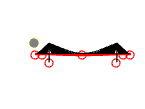

% figure(fig)
% plot3(ax,X,Y,Z,'Color','b','LineWidth',1)
view([0,-1,0])
ax.Visible = "off";

function [fig,ax,X_shape,Y_shape,Z_shape] = getBeamElementGlobalForce(elems_shape,elems_monitered,direction,type_elems_monitered,type_force,options)
    arguments
        elems_shape
        elems_monitered % 按照顺序排列
        direction  {mustBeMember(direction,{'X','Z'})}
        type_elems_monitered {mustBeMember(type_elems_monitered,{'Beam','Link'})}
        type_force {mustBeMember(type_force,{'Fx','My'})}
        options.Figure = figure
        options.Axis = axes
    end
    % 作图：单元形状
    [fig,ax,X_shape,Y_shape,Z_shape] = elems_shape.plot('Figure',options.Figure,'Axis',options.Axis);

    % 作图：单元内力
    Fxi_local = [];
    Fxj_local = [];
    Myi_local = [];
    Myj_local = [];
    Mzi_local = [];
    Mzj_local = [];
    force_local = [elems_monitered.Force_LocalCoord];
    if strcmp(type_elems_monitered,'Beam')
        switch type_force
            case 'Fx'
                Fxi_local = force_local(1,:);
                Fxj_local = force_local(2,:);
            case 'My'
                Myi_local = force_local(5,:);
                Myj_local = force_local(11,:);
                Mzi_local = force_local(6,:);
                Mzj_local = force_local(12,:);
        end
         
    end
    if strcmp(type_elems_monitered,'Link')
        switch type_force
            case 'Fx'
                Fxi_local = force_local(1,:);
                Fxj_local = force_local(2,:);
            case 'My'
                error('Link单元不存在弯矩')
        end
    end

    
    for i=1:length(elems_force)
        
    end
    
    
end
function [fig,ax] = plotDisplacement()
end
function [X_nodes,Y_nodes,Z_Uz,Uz,fig,ax] = plotTowerBendingMoment(bridgeobj,multiplier,fig,ax)
    structures = bridgeobj.findStructureByClass('Girder');
    nodes = [];
    inodes = [];
    jnodes = [];
    for i=1:length(structures)
        structure = structures{i};
        elems = structure.Element;
        inodes = [inodes,elems.INode];
        jnodes = [jnodes,elems.JNode];
    end
    nodes = [inodes,jnodes];
    sorted_nodes = nodes.sort('X');
    Displacement_GlobalCoord = [sorted_nodes.Displacement_GlobalCoord];
    Uz = Displacement_GlobalCoord(3,:);

    X_nodes = [sorted_nodes.X];
    Y_nodes = [sorted_nodes.Y];
    Z_nodes = [sorted_nodes.Z];
    Z_Uz = Z_nodes + multiplier*Uz/max(abs(Uz));
    figure(fig)
    plot3(ax,X_nodes,Y_nodes,Z_Uz,'Color','r','LineWidth',1)
end

